tffile='nucleon_naive_proportional - Copy.tfi';

ans = 'LiveEditorEvaluationHelperE1683735183'

tf=ReadTF(tffile)

tf =     0.1349    0.6000         0    1.0000         0
    0.1577    0.5059    0.3529    1.0000    0.1020
    0.1806    0.5686    0.3059    0.8667         0
    0.3978    1.0000         0         0         0
    0.4436    1.0000         0         0    0.3020
    0.4894    1.0000         0         0         0
    0.7550    0.0157    1.0000         0         0
    0.8606    0.2863    1.0000    0.0039    0.6000
    0.9663    0.0314    1.0000    0.0275         0


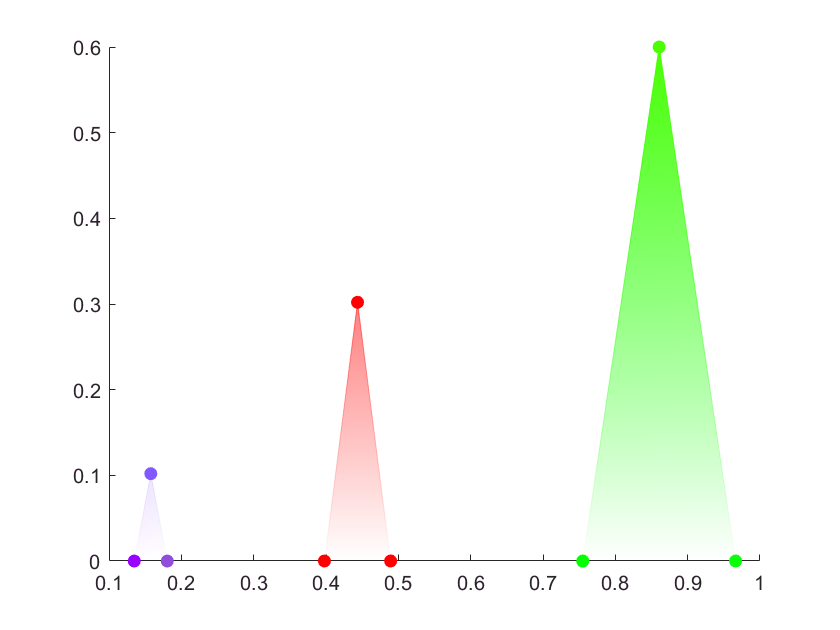

ShowTF(tf)

[~,name,~] = fileparts(tffile);
WriteTF(tf, [name,'.xml'])


<?xml version="1.0" encoding="utf-8"?>
<VoreenData version="1">
   <TransFuncIntensity type="TransFuncIntensity">
      <alphaMode value="1"/>
      <gammaValue value="1"/>
      <domain x="0" y="1"/>
      <threshold x="0" y="1"/>
      <Keys>
         <key type="TransFuncMappingKey">
            <intensity value="0.13492"/>
            <split value="false"/>
            <colorL a="0" b="255" g="0" r="153"/>
         </key>
         <key type="TransFuncMappingKey">
            <intensity value="0.15774"/>
            <split value="false"/>
            <colorL a="26" b="255" g="90" r="129"/>
         </key>
         <key type="TransFuncMappingKey">
            <intensity value="0.18056"/>
            <split value="false"/>
            <colorL a="0" b="221" g="78" r="145"/>
         </key>
         <key type="TransFuncMappingKey">
            <intensity value="0.39782"/>
            <split value="false"/>
            <colorL a="0" b="0" g="0" r="255"/>
         </key>
         <key typ

function result = ReadTF(tffile)
    xDoc=xmlread(tffile);
    intensityList=xDoc.getElementsByTagName('intensity');
    colorLList=xDoc.getElementsByTagName('colorL');
    range=0:min(intensityList.getLength,colorLList.getLength)-1;
    intensity=arrayfun(@(i) str2double(intensityList.item(i).getAttribute('value')),range);
    r=arrayfun(@(i) str2double(colorLList.item(i).getAttribute('r'))/255,range);
    g=arrayfun(@(i) str2double(colorLList.item(i).getAttribute('g'))/255,range);
    b=arrayfun(@(i) str2double(colorLList.item(i).getAttribute('b'))/255,range);
    a=arrayfun(@(i) str2double(colorLList.item(i).getAttribute('a'))/255,range);
    result=[intensity;r;g;b;a].';
end

function ShowTF(tf)
    a=tf(:,5);
    mymap=tf(:,2:4);
    data=tf(:,[1 5]);
    faces=1:length(a);
    patch('Vertices',data,'Faces',faces,'FaceVertexCData',mymap,'FaceVertexAlphaData',a,'EdgeColor','interp','EdgeAlpha','interp','FaceColor','interp','FaceAlpha','interp','Marker','o','MarkerFaceColor','flat');
end

function WriteTF(tf, tffile)
    tfi=[tf(:,1) round(tf(:,2:5).*255)];
    m = size(tf,1);
    
    docNode = com.mathworks.xml.XMLUtils.createDocument('VoreenData');
    docNode.appendChild(docNode.createComment('This is a Voreen transfer function created using MATLAB.'));
    docRootNode = docNode.getDocumentElement;
    docRootNode.setAttribute('version','1');
    TransFuncIntensity=docNode.createElement('TransFuncIntensity');
    TransFuncIntensity.setAttribute('type','TransFuncIntensity');
    alphaMode=docNode.createElement('alphaMode');
    alphaMode.setAttribute('value','1');
    gammaValue=docNode.createElement('gammaValue');
    gammaValue.setAttribute('value','1');
    domain=docNode.createElement('domain');
    domain.setAttribute('x','0');
    domain.setAttribute('y','1');
    threshold=docNode.createElement('threshold');
    threshold.setAttribute('x','0');
    threshold.setAttribute('y','1');
    Keys=docNode.createElement('Keys');
    docRootNode.appendChild(TransFuncIntensity);
    TransFuncIntensity.appendChild(alphaMode);
    TransFuncIntensity.appendChild(gammaValue);
    TransFuncIntensity.appendChild(domain);
    TransFuncIntensity.appendChild(threshold);
    TransFuncIntensity.appendChild(Keys);
    
    for i=1:m
        key = docNode.createElement('key');
        key.setAttribute('type','TransFuncMappingKey');
        intensity = docNode.createElement('intensity');
        intensity.setAttribute('value',num2str(tfi(i,1)));
        split = docNode.createElement('split');
        split.setAttribute('value','false');
        colorL = docNode.createElement('colorL');
        colorL.setAttribute('r',num2str(tfi(i,2)));
        colorL.setAttribute('g',num2str(tfi(i,3)));
        colorL.setAttribute('b',num2str(tfi(i,4)));
        colorL.setAttribute('a',num2str(tfi(i,5)));
        key.appendChild(intensity);
        key.appendChild(split);
        key.appendChild(colorL);
        Keys.appendChild(key);
    end
    
    xmlwrite(tffile,docNode);
    type(tffile);
end